# FMCW Radar Lab: Range-Doppler Response

In this lab, you will see how we can utlize the Doppler shift due to radial target velocity to more clearly see moving targets. To do this, we collect more than one pulse at a time. The Fourier transform is taken across pulses - the radial velocity of the target is proportional to the observed frequency.

## System Setup

Before going through the lab, we prepare the workspace by clearing variables, closing figures, suppressing warnings.

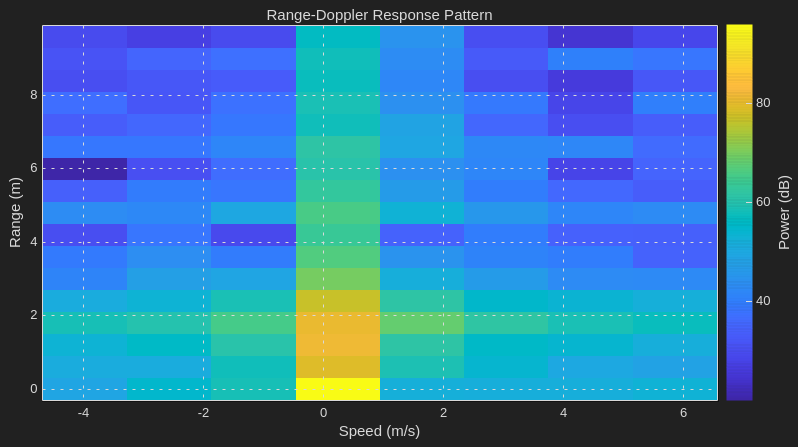

clear;

close all;

We need to set the id of the Phaser board being used.

id = 'AcTmTkmoyG';

For this lab, we use many of the same parameters that were used in lab 1.

The operating frequency of the radar is 10 GHz.

fc = 10e9;

The PRF will impact the maximum radial target velocity that we can observe unambiguously when performing Doppler processing. If we send out pulses more frequently, we will be able to observe targets moving with higher velocities. If we send out pulses less frequenctly, targets with high velocities will alias into the lower frequency Doppler region. Try changing the PRF to see the effect that it has.

prf = 1000;

The number of pulses that we process together will impact the Doppler resolution and gain when performing Doppler processing. With more pulses, we are able to resolve a targets velocity more clearly and we get more processing gain. Try changing the number of pulses to see the effect that it has.

nPulses = 16;

We set the sampling rate to be 600 KHz.

fs = 600e3;

We set the number of samples to 150. This controls the number of samples from each waveform sweep are received. This will impact our maximum resolvable range.

ns = 150;

We set the ramp bandwidth of the system to be 500 MHz.

rampbandwidth = 500e6;

Finally, we set up the FMCW radar with these key system parameters. Each of the outputs of the function below are responsible for controlling some part of the radar.

radar = setupRemoteRadar(id,prf,nPulses,fs,rampbandwidth,ns);

## Data Collection

With our FMCW radar configured. It is time to capture some radar data and visualize the range response.

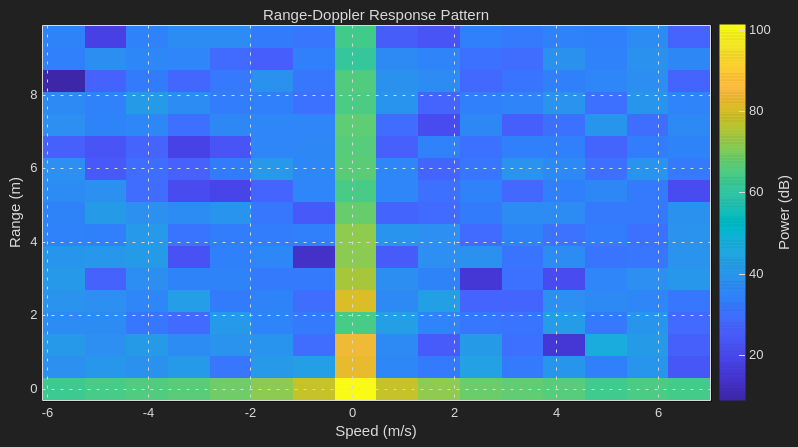

% Run time in seconds
tCapture = 30;

% Get the min and max ranges to include on the plot
minRange = 0;
maxRange = 10;

% Create a range-Doppler response for processing
tSweep = get(radar,'ramp_time');
trueBw = get(radar,'ramp_bandwidth');
sweepSlope = trueBw/tSweep;
rd = phased.RangeDopplerResponse(DopplerOutput="Speed",...
    OperatingFrequency=fc,SampleRate=fs,RangeMethod="FFT",...
    SweepSlope=sweepSlope,PRFSource="Property",PRF=prf);

% Create a range-Doppler scope for plotting
scope = phased.RangeDopplerScope(IQDataInput=false,DopplerLabel="Speed (m/s)");
scope.Position = [50 50 800 450];

t = tic;
while toc(t) < tCapture
    % capture data
    data = radar.rx();

    % Sum the two receive channels
    data = squeeze(sum(data,2));

    % Get the response
    [resp,range,speed] = rd(data);

    % Get range of interest
    keepRange = range >= minRange & range <= maxRange;

    scope(resp(keepRange,:),range(keepRange),speed);
end